Definizione del **numeratore** e del **denominatore** della **FdT**.

num = 1;
den = [1 0 1];

sys = tf(num,den)


sys =
 
     1
  -------
  s^2 + 1
 
Continuous-time transfer function.
Model Properties


Calcolo dei **poli** del sistema dinamico.

pole(sys)

ans =    0.0000 + 1.0000i
   0.0000 - 1.0000i


Tracciamento del **diagramma di Bode**.

- Il termine trinomio ha smorzamento nullo, si ha un picco elevatissimo in corrispondenza della pulsazione naturale 𝑤𝑛 = 1e una discontinuità netta per quanto riguarda la fase.

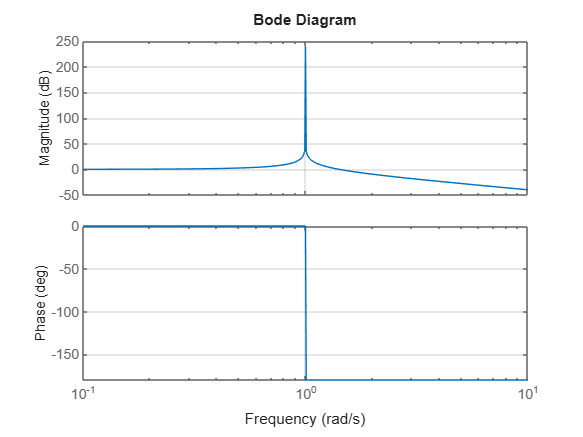

bode(sys);
grid on

Calcolo di** modulo** e** fase** per diversi valori di **w.**

[mag,phase,wout] = bode(sys);